## Tópicos especiais em Estatística Aplicada - 2023/2

## Aluno: João Gabriel Santos Custodio

% data collection from "iris.txt"
opts = detectImportOptions('iris.txt');
opts.SelectedVariableNames=[1 2 3 4];
Mread = readmatrix("iris.txt",opts); 

%Setosa data
sepal_lenght_s = Mread(1:50,1);
sepal_width_s = Mread(1:50,2);
petal_lenght_s = Mread(1:50,3);
petal_width_s = Mread(1:50,4); 

%Versicolor data
sepal_lenght_ve = Mread(51:100,1);
sepal_width_ve = Mread(51:100,2);
petal_lenght_ve = Mread(51:100,3);
petal_width_ve = Mread(51:100,4); 

%Virginica data
sepal_lenght_vir = Mread(101:150,1);
sepal_width_vir = Mread(101:150,2);
petal_lenght_vir = Mread(101:150,3);
petal_width_vir = Mread(101:150,4); 

## 1. Veja o gráfico mais adequado para mostrar se há diferença entre a média, mediana, desvio padrão e curtose da largura da sépala das três espécie.

O gráfico de barras é o mais apropriado para apresentar as medidas, pois a altura das barras destaca diferentes escalas e a separação das classes é visualmente clara devido à distância entre os grupos de barras, como demonstrado no gráfico a seguir:

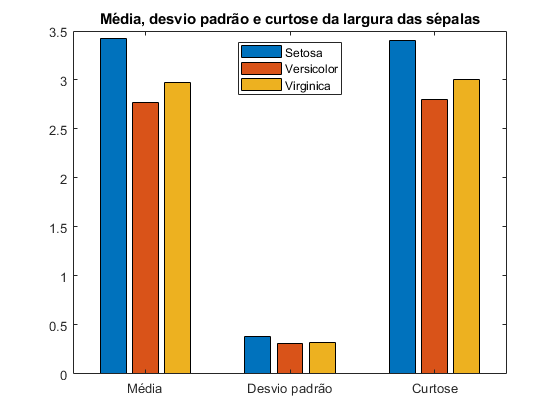

%Cálculo das médias, medianas, desvio padrões e curtoses
%mean
m_s = mean(sepal_width_s);
m_ve = mean(sepal_width_ve);
m_vir = mean(sepal_width_vir);

%median
median_s = median(sepal_width_s);
median_ve = median(sepal_width_ve);
median_vir = median(sepal_width_vir);

%Standard deviation
std_s = std(sepal_width_s);
std_ve = std(sepal_width_ve);
std_vir = std(sepal_width_vir);

%kurtosis
%k_s = kurtosis(sepal_width_s);
%k_ve = kurtosis(sepal_width_ve); 
%k_vir = kurtosis(sepal_width_vir);

figure
X = categorical({'Média','Desvio padrão','Curtose'});
X = reordercats(X,{'Média','Desvio padrão','Curtose'});
y = [m_s m_ve m_vir; std_s std_ve std_vir; median_s median_ve median_vir];
bar(X,y)
title("Média, desvio padrão e curtose da largura das sépalas"); 
legend("Setosa","Versicolor","Virginica",'Location','north'); 

Analisando visualmente o gráfico de barras, podemos concluir que todos os conjuntos de dados têm um baixo desvio padrão. Isso é indicado pela proximidade das alturas das barras em relação à linha média, o que sugere que os valores estão agrupados mais próximos à média e não se espalham significativamente.

## 2. Verifique graficamente se há evidências de correlação entre o comprimento e largura da pétala para as 3

## espécies do dataset.

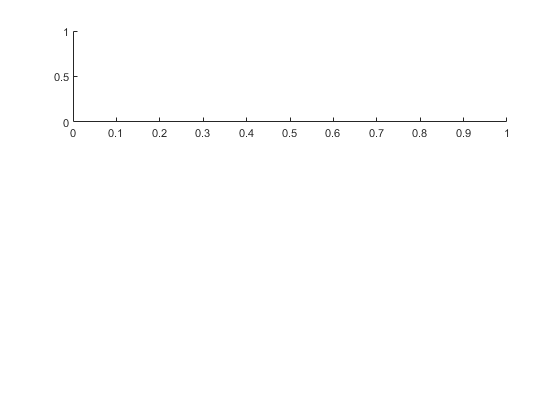

figure
subplot(3,1,1)

boxplot([petal_lenght_s, petal_width_s],"Labels",["Comprimento" , "Largura"]) 

'boxplot' requires Statistics and Machine Learning Toolbox.

title("Medições para as pétalas da espécie Setosa");
subplot(3,1,2)
boxplot([petal_lenght_vir, petal_width_vir],"Labels",["Comprimento" , "Largura"])
title("Medições para as pétalas da espécie Virginica");
subplot(3,1,3)
boxplot([petal_lenght_ve, petal_width_ve],"Labels",["Comprimento" , "Largura"]) ;
title("Medições para as pétalas da espécie Versicolor"); 

Ao examinar os boxplots apresentados anteriormente, é possível concluir que não há evidências que sugiram uma correlação entre o comprimento e a largura das pétalas das espécies presentes no conjunto de dados.